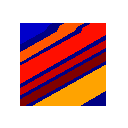

clear;
clc;
addpath('D:\Matlab\Data');
HSI = importdata('Data\SalinasA.mat');
HSI_gt = importdata('Data\SalinasA_gt.mat');

% Salinas:0.7,1:0.1:7,no normalization,k=17,Neighbor=1200,MNF11,W+W'
% SalinasA:0.3,1:0.1:10,no normalization,k=15,Neighbor=1000,no MNF
HSI(:, :, 224) = [];
HSI(:, :, 154:167) = [];
HSI(:, :, 108:112) = [];

gt = double(HSI_gt(:));
nall = length(gt);
loc = find(HSI_gt ~= 0);
gtnum = length(unique(gt)) -1 ;
gt_nobg = gt;
gt_nobg(gt_nobg == 0) = [];

imshow(HSI_gt, [], 'Border', 'tight');
colormap('jet');

% impixelinfo;

% compare
addpath('D:\Matlab\Clustering--based--density--peaks-master');
addpath('D:\Matlab\FINCH-Clustering\FINCH-Clustering-master\matlab');
addpath('D:\Matlab\Matlab_MNF-master\Matlab_MNF-master');
addpath('D:\Matlab\SSC-using-ADMM');
addpath('D:\Matlab\symnmf-master\symnmf-master');
addpath('D:\Matlab\SSC-master\SSC-master');
addpath('D:\Matlab\ClusteringDirectionCentrality');
addpath('D:\Matlab\KCCE');

ind = L;
ind(gt == 0) = [];
lab = ind;
tmp = sort(unique(ind));
k = 1;
for i = 1:length(tmp)
    lab(ind == tmp(i)) = k;
    k = k + 1;
end
k = k - 1;

% Kmeans
classnum = gtnum;

[label_kmeans, ~] = kmeans(Z, classnum, 'Replicates', 1);

kme = zeros(length(lab), 1);
for i = 1:length(lab)
    kme(i) = label_kmeans(lab(i));
end

[~, kme] = label_corrected(kme, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, kme)

OA = 0.7792

Kappa = 0.7226

PA =     1.0000
    0.5800
         0
    0.9993
    1.0000
    1.0000


UA =     1.0000
    0.5653
         0
    0.9890
    0.5785
    0.9173


[ARI, ~, ~, ~] = ari(gt_nobg, kme)

ARI = 0.7167

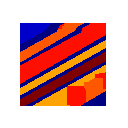

figure;

img = zeros(nall, 1);
img(loc, :) = kme;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');

% FCM
classnum = gtnum;

[centers, U] = fcm(Z, classnum);

Iteration count = 1, obj. fcn = 53.699379
Iteration count = 2, obj. fcn = 40.101790
Iteration count = 3, obj. fcn = 36.451323
Iteration count = 4, obj. fcn = 29.136164
Iteration count = 5, obj. fcn = 25.092961
Iteration count = 6, obj. fcn = 21.170432
Iteration count = 7, obj. fcn = 11.688940
Iteration count = 8, obj. fcn = 8.442782
Iteration count = 9, obj. fcn = 7.735955
Iteration count = 10, obj. fcn = 7.693950
Iteration count = 11, obj. fcn = 7.687530
Iteration count = 12, obj. fcn = 7.685973
Iteration count = 13, obj. fcn = 7.685549
Iteration count = 14, obj. fcn = 7.685430
Iteration count = 15, obj. fcn = 7.685397
Iteration count = 16, obj. fcn = 7.685387


label_fcm = zeros(n, 1);
for p = 1:k
    label_fcm(p) = find(U(:, p) == max(U(:, p)));
end

fcm_ = zeros(length(lab), 1);
for i = 1:length(lab)
    fcm_(i) = label_fcm(lab(i));
end

[~, fcm_] = label_corrected(fcm_, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, fcm_)

OA = 0.7792

Kappa = 0.7229

PA =     1.0000
    0.5800
         0
    0.9993
    1.0000
    1.0000


UA =     1.0000
    0.5653
         0
    0.9890
    0.7642
    1.0000


[ARI, ~, ~, ~] = ari(gt_nobg, fcm_)

ARI = 0.7514

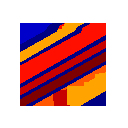

figure;

img = zeros(nall, 1);
img(loc, :) = fcm_;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');

% FINCH
classnum = gtnum;

[label_finch, num_clust]= FINCH(Z, [], 1);

Partition 1 : 15 clusters
Partition 2 : 9 clusters


label_finch= req_numclust(label_finch(:, 2), Z, classnum);

finch = zeros(length(lab), 1);
for i = 1:length(lab)
    finch(i) = label_finch(lab(i));
end

[~, finch] = label_corrected(finch, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, finch)

OA = 0.7001

Kappa = 0.6120

PA =     1.0000
    0.2651
         0
    0.9993
    1.0000
    1.0000


UA =     1.0000
    1.0000
         0
    0.4875
    1.0000
    1.0000


[ARI, ~, ~, ~] = ari(gt_nobg, finch)

ARI = 0.4516

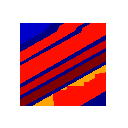

figure;

img = zeros(nall, 1);
img(loc, :) = finch;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');

% SSC
classnum = gtnum;

[~, label_ssc] = SSC(Z', 4, false, 18, false, 1, classnum);

err1: 0.0002, err2: 0.1374, iter: 108 



% [C, ~, ~, ~, ~] = SSC_viaADMM(Z');
% cmax = max(C);
% cmax_ = repmat(cmax, k, 1);
% C = C ./ cmax_;
% C = abs(C);
% W_ssc = C + C';

% label_ssc = spectralcluster(W_ssc, classnum, 'Distance', 'precomputed');

ssc = zeros(length(lab), 1);
for i = 1:length(lab)
    ssc(i) = label_ssc(lab(i));
end

[~, ssc] = label_corrected(ssc, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, ssc)

OA = 0.8409

Kappa = 0.7976

PA =     0.7442
    0.9993
    0.0276
    0.9010
    1.0000
    1.0000


UA =     0.9932
    0.9970
    0.1018
    0.7344
    0.8731
    0.8888


[ARI, ~, ~, ~] = ari(gt_nobg, ssc)

ARI = 0.7687

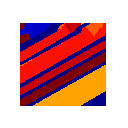

figure;

img = zeros(nall, 1);
img(loc, :) = ssc;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');

Computing Rho with gaussian kernel of radius:     0.116665
Generated file:DECISION GRAPH


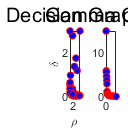

NUMBER OF CLUSTERS: 6 
assignation
CLUSTER: 1 CENTER: 10 ELEMENTS: 6 CORE: 6 HALO: 0 
CLUSTER: 2 CENTER: 13 ELEMENTS: 18 CORE: 18 HALO: 0 
CLUSTER: 3 CENTER: 17 ELEMENTS: 12 CORE: 12 HALO: 0 
CLUSTER: 4 CENTER: 19 ELEMENTS: 2 CORE: 2 HALO: 0 
CLUSTER: 5 CENTER: 29 ELEMENTS: 13 CORE: 13 HALO: 0 
CLUSTER: 6 CENTER: 36 ELEMENTS: 14 CORE: 14 HALO: 0 


% FSFDP
classnum = gtnum;

label_fsfdp = FSFDP(Z, classnum);

label_fsfdp = label_fsfdp';

fsfdp = zeros(length(lab), 1);
for i = 1:length(lab)
    fsfdp(i) = label_fsfdp(lab(i));
end

[~, fsfdp] = label_corrected(fsfdp, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, fsfdp)

OA = 0.7792

Kappa = 0.7221

PA =     1.0000
    0.5800
         0
    0.9993
    1.0000
    1.0000


UA =     1.0000
    0.5653
         0
    0.9890
    0.7650
    0.6918


[ARI, ~, ~, ~] = ari(gt_nobg, fsfdp)

ARI = 0.7013

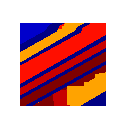

figure;

img = zeros(nall, 1);
img(loc, :) = fsfdp;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');

% SC
classnum = gtnum;

% label_sc = spectralcluster(Z, classnum);

W_sc = exp(-squareform((pdist(Z) / 1).^2));
T1 = diag(1 ./ sqrt(sum(W_sc)));
W_sc = T1 * W_sc * T1;
W_sc = roundn(W_sc, -4);

label_sc = spectralcluster(W_sc, gtnum, 'Distance', 'precomputed');

sc = zeros(length(lab), 1);
for i = 1:length(lab)
    sc(i) = label_sc(lab(i));
end

[~, sc] = label_corrected(sc, gt_nobg);
[OA, Kappa, PA, UA] = calaccuracy(gt_nobg, sc)

OA = 0.7633

Kappa = 0.7034

PA =     1.0000
    0.5168
         0
    0.9993
    1.0000
    1.0000


UA =     1.0000
    0.5367
         0
    0.9890
    0.5098
    1.0000


[ARI, ~, ~, ~] = ari(gt_nobg, sc)

ARI = 0.7230

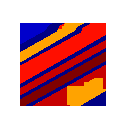

figure;

img = zeros(nall, 1);
img(loc, :) = sc;
img = reshape(img, [], m);
imshow(img, [], 'Border','tight');
colormap('jet');